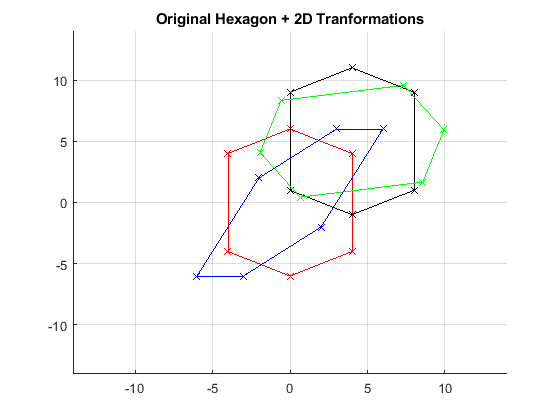

clc;
clear all;

% Plot points in Cartesian system and connect the 6 points

h = [0 12 2; 16 16 4; 12 -12 3; 0 -36 6; -20 -20 5; -28 28 7];
c = hom2cart(h);
x_cord = c(:,1:1);
y_cord = c(:,2:2);

hold on
c1 = transpose(c);
axis([-14 14 -14 14]);
plot(c1(1,1:end),c1(2,1:end),'rx-');
plot([-4 0],[4 6],'rx-');

grid on 

% Homogenous Transformation: Rotation, Translate, Sheer

t1=4;
t2=5;
It1=[1 0 t1;0 1 t2;0 0 1];
% H = [0,16,12,0,-20,-28,0; 12,16,-12,-36,-20,28,12; 2,4,3,6,5,7,2];
H =[0 4 4 0 -4 -4 0; 6 4 -4 -6 -4 4 6; 1 1 1 1 1 1 1];
p1= It1*H;

plot(p1(1,1:end),p1(2,1:end),'kx-');
c1 = hom2cart(p1);
 
Rt = [cos(30) -sin(30) t1; sin(30) cos(30) t2; 0 0 1];
p2= Rt*H;
plot(p2(1,1:end),p2(2,1:end),'gx-');
c2 = hom2cart(p2);
 
Shear = [1 0.5 0; 0.5 1 0; 0 0 1];
p3 = Shear*H;
plot(p3(1,1:end),p3(2,1:end),'bx-');
c3 = hom2cart(p3);
 title('Original Hexagon + 2D Tranformations')
 hold off

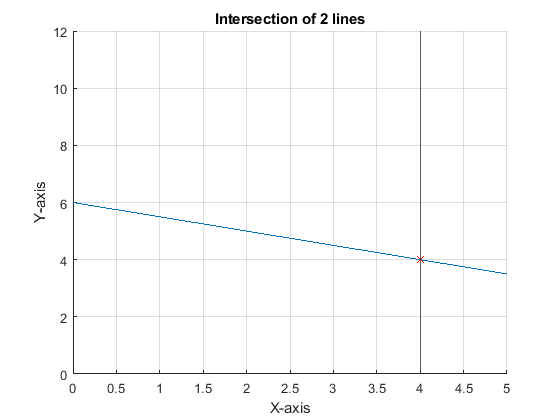

 
% Intersection of points
figure(2)
x = 0 : 5;
m = -0.5;
b = 6;
y = m*x + b;

hold on
plot(x, y);
grid
axis([0  5    0  12]);
xline(4);
plot(4,4,'rx');
hold off

title('Intersection of 2 lines');
xlabel('X-axis');
ylabel('Y-axis');